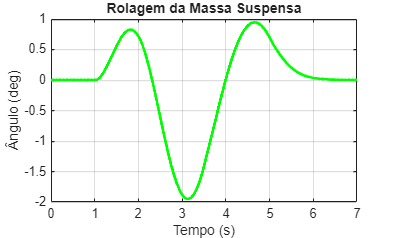

=== RMS Values ===


RMS - Suspended Mass Roll: 0.6344 deg


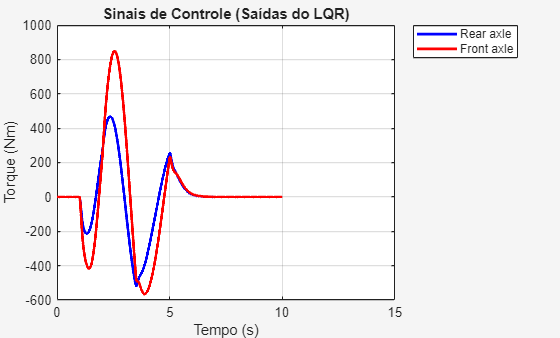

=== RMS LQR Values ===


RMS - Suspended Mass Roll: 0.6344 deg


RMS - Front Unsprung Roll: 0.4810 deg


RMS - Rear Unsprung Roll: 0.4444 deg


%% Limpeza Inicial
clear;         % Limpa todas as variáveis (mais seguro que clear)

clc;               % Limpa a janela de comandos
close all;         % Fecha todas as figuras

%% Massa e Inércia
global ms muf mur m Ixx Ixz Izz
ms = 12487;          % Massa suspensa (kg)
m = 14193;           % Massa total do veículo (kg)
Ixx = 24201;         % Momento de inércia de rolagem (kg.m²)
Ixz = 4200;          % Produto de inércia yaw-roll (kg.m²)
Izz = 34917;         % Momento de inércia de guinada (kg.m²)

%% Geometria do Veículo
muf = 706;           % Massa não suspensa no eixo dianteiro (kg)
mur = 1000;          % Massa não suspensa no eixo traseiro (kg)
global h hu rr rf lf lr lw
h = 0.83;            % Altura do CG da massa suspensa (m)
hu = 0.53;           % Altura do CG da massa não suspensa (m)
rf = 1.15;            % Altura do eixo de rolagem ao solo (m)
rr = 1.15;            % Altura do eixo de rolagem ao solo (m)
lf = 1.95;           % Distância do CG ao eixo dianteiro (m)
lr = 1.54;           % Distância do CG ao eixo traseiro (m)
lw = 0.93;           % Metade da largura do veículo (m)

%% Parâmetros de Suspensão e Pneus
global kf kr bf br ktf ktr Cf Cr
kf = 380000;         % Rigidez de rolagem da suspensão dianteira (Nm/rad)
kr = 684000;         % Rigidez de rolagem da suspensão traseira (Nm/rad)
bf = 100000;         % Amortecimento de rolagem dianteiro (Nm/rad)
br = 100000;         % Amortecimento de rolagem traseiro (Nm/rad)
ktf = 2060000;       % Rigidez de rolagem do pneu dianteiro (Nm/rad)
ktr = 3337000;       % Rigidez de rolagem do pneu traseiro (Nm/rad)
Cf = 582000;         % Rigidez lateral do pneu dianteiro (N/rad)
Cr = 783000;         % Rigidez lateral do pneu traseiro (N/rad)

%% Parâmetros da Barra Estabilizadora
% global Df Dr E tA tB c kAO_f kAO_r
Df = 32;             % Diâmetro externo da barra estabilizadora dianteira (mm)
Dr = 34;             % Diâmetro externo da barra estabilizadora traseira (mm)
% E = 206000;          % Módulo de Young do material (MPa)
tAf = 2.4076;
tBf = 0.6593;
cf = 0.8931;
tAr = 2.8629;
tBr = 0.4113;
cr = 0.7651;
kAO_f = 10730;       % Rigidez da Barra Dianteira (Nm/rad)
kAO_r = 15480;       % Rigidez da Barra Traseira (Nm/rad)

%% Aderência do Solo
global mu g
mu = 1;              % Coeficiente de aderência ao solo
g = 9.81;            % Gravidade (m/s²)

%% Informações de Controle e Manobra
global v
v = 50 / 3.6;        % Velocidade longitudinal (m/s)

% Momentos da Barra Estabilizadora Passiva
MARf_phi = (4 * kAO_f * ((tAf * tBf) / cf^2));
MARr_phi = (4 * kAO_r * ((tAr * tBr) / cr^2));
MARf_phi_uf = -(4 * kAO_f * (tAf^2 / cf^2));
MARr_phi_ur =  -(4 * kAO_r * (tAr^2 / cr^2));


% % Momentos da Barra Estabilizadora Passiva
% MARf_phi = 0;
% MARr_phi = 0;
% MARf_phi_uf = 0;
% MARr_phi_ur = 0;

% Definição da Matriz E
E_mat = [ m*v, 0, 0, -ms*h, 0, 0;
    0, Izz, 0, -Ixz, 0, 0;
    ms*v*h, Ixz, -bf - br, -(Ixx + ms*(h^2)), bf, br;
    muf*v*(rf-hu), 0,  bf, 0, -bf, 0;
    mur*v*(rr-hu), 0,  br, 0, 0, -br;
    0,0,1,0,0,0];

% Definição da Matriz F
F_mat = [ 0, m*v, 0, 0, 0, 0;
    0, 0, 0, 0, 0, 0;
    0, ms*v*h, (ms*g*h) - (kf + MARf_phi) - (kr + MARr_phi), -bf - br, (kf + MARf_phi_uf), (kr + MARr_phi_ur);
    0, muf*v*(rf-hu), (kf + MARf_phi), bf, (muf*g*hu) - ktf - (kf + MARf_phi_uf), 0;
    0, mur*v*(rr-hu), (kr + MARr_phi), br, 0, (-mur*g*hu) - ktr - (kr + MARr_phi_ur);
    0,0,0,-1,0,0];

H_common = [ 1, 1;
    lf, -lr;
    0, 0;
    -rf, 0;
    0, -rr;
    0, 0];

G = [ 0, 0;
    0, 0;
    -1, -1;
    0, -1;
    -1, -1;
    0, 0];

B_control  = E_mat \ G;
B_passive  = E_mat \ H_common;
B_ativo    = [B_passive, B_control];

C_ativo  = eye(6);
A_ativo = -E_mat \ F_mat;
D_ativo = zeros(size(C_ativo,1), size(B_ativo,2));

assignin('base', 'A_ativo', A_ativo);
assignin('base', 'B_ativo', B_ativo);
assignin('base', 'D_ativo', D_ativo);

% Definir o tempo e o sinal
t = linspace(0, 10, 1000)'; % Tempo como vetor coluna
delta = zeros(size(t)); % Inicializa o vetor do ângulo de direção

% Definir os tempos das mudanças de faixa
t1 = 1;
t2 = 2;
t3 = 3.5;
tf = 5;

% Criar o perfil de esterçamento (Double Lane Change)
delta = (t >= t1 & t < t2) .* (2 * sin(pi * (t - t1) / (t2 - t1))) + ...
    (t >= t2 & t < t3) .* (-4 * sin(pi * (t - t2) / (t3 - t2))) + ...
    (t >= t3 & t < tf) .* (2 * sin(pi * (t - t3) / (tf - t3)));

% Criar uma variável de sinal compatível com Simulink
steering_signal = [t, delta];

% Salvar no Workspace
assignin('base', 'steering_signal', steering_signal);

%% Redução do Modelo: Projeção dos Estados Controláveis
T = [0 0 1 0 0 0;
    0 0 0 1 0 0;
    0 0 0 0 1 0;
    0 0 0 0 0 1];

A_r = T * A_ativo * pinv(T);
B_r = T * B_control;

%% Definição do controlador LQR

Q_r = diag([1e10, 5e7, 2e7, 2e7]);
R_r = diag([1e-2, 1e-2]);


K_r = lqr(A_r, B_r, Q_r, R_r);             % ganho ótimo

% Envia para o Simulink
assignin('base', 'K_r', K_r);

% %% Sweep Refinado de R para Melhorar RMS
% 
% % Mantém o Q_r atual
% Q_r = diag([30000, 20000, 10000, 10000]);
% 
% % Valores de R_r para testar
% Rr_testes = logspace(log10(2e-5), log10(5e-5), 5);
% 
% % Inicializar resultados
% melhorRMS = inf;
% melhorRr = [];
% melhorK_r = [];
% 
% fprintf('==> Iniciando Sweep Refinado de R\n');
% for i = 1:length(Rr_testes)
% 
%     % Define o R_r da rodada
%     R_r = diag([Rr_testes(i), Rr_testes(i)]);
% 
%     % Recalcula o ganho LQR
%     try
%         [K_r, ~, ~] = lqr(A_r, B_r, Q_r, R_r);
% 
%         % Coloca no workspace (para Simulink)
%         assignin('base', 'K_r', K_r);
%         assignin('base', 'T', T);
%         assignin('base', 'A_r', A_r);
%         assignin('base', 'B_r', B_r);
% 
%         % Roda Simulink
%         simOut = sim('ARB_ACTIVE_LQR', 'ReturnWorkspaceOutputs', 'on');
% 
%         % Pega os sinais
%         if isprop(simOut, 'ativo_LQR')
%             data = rad2deg(simOut.ativo_LQR);
% 
%             % Calcula o RMS da rolagem da massa suspensa (coluna 3)
%             rms_phi = rms(data(:,3));
% 
%             fprintf('R_r = %.1e -> RMS = %.4f graus\n', Rr_testes(i), rms_phi);
% 
%             % Atualiza o melhor
%             if rms_phi < melhorRMS
%                 melhorRMS = rms_phi;
%                 melhorRr = Rr_testes(i);
%                 melhorK_r = K_r;
%             end
%         else
%             warning('Sinal "ativo_LQR" não encontrado.');
%         end
% 
%     catch
%         warning('Erro para R_r = %.1e', Rr_testes(i));
%     end
% end
% 
% % Mostra o melhor encontrado
% fprintf('\n=== Melhor Configuração Encontrada ===\n');
% fprintf('Melhor R_r = %.1e\n', melhorRr);
% fprintf('Melhor RMS = %.4f graus\n', melhorRMS);
% 
% % Atualiza o K_r final no workspace
% assignin('base', 'K_r', melhorK_r);

model = 'ARB_ACTIVE_LQR';

% Define o parâmetro swtc no workspace
swtc = Simulink.Parameter;
swtc.Value = 0;  % valor padrão (pode ser sobrescrito nas simulações)

% Setup para swtc = 1
simIn1 = Simulink.SimulationInput(model);
simIn1 = simIn1.setVariable('swtc', 1);

% Setup para swtc = 0
simIn0 = Simulink.SimulationInput(model);
simIn0 = simIn0.setVariable('swtc', 0);

% Executa simulações — retorna objetos SimulationOutput automaticamente
simOut1 = sim(simIn1);
simOut0 = sim(simIn0);

% Extração dos dados (exemplo para 'ativo_LQR')
data1.time = simOut1.tout(:);
data1.ativo = squeeze(simOut1.ativo_LQR)';
data0.time = simOut0.tout(:);
data0.ativo = squeeze(simOut0.ativo_LQR)';

% Plot comparativo
figure;
plot(data1.time, rad2deg(data1.ativo(:,3)), 'g', 'LineWidth', 2); hold on;
plot(data0.time, rad2deg(data0.ativo(:,3)), 'b--', 'LineWidth', 2);
grid on;
title('Rolagem Suspensa: SWTC = 1 (verde) vs SWTC = 0 (azul)');
xlabel('Tempo (s)');
ylabel('Ângulo (deg)');
legend('swtc = 1', 'swtc = 0');
xlim([0 7]);

% Extrai os sinais de controle das simulações
u1 = simOut1.controles_LQR;  % swtc = 1
u0 = simOut0.controles_LQR;  % swtc = 0

t1 = simOut1.tout(:);
t0 = simOut0.tout(:);

% === Figura: Sinais de Controle Comparativos ===
figure;

subplot(2,1,1);
plot(t1, u1(:,1), 'g', 'LineWidth', 1.5); hold on;
plot(t0, u0(:,1), 'b--', 'LineWidth', 1.5);
grid on;
title('Sinal de Controle - Eixo Traseiro');
xlabel('Tempo (s)');
ylabel('Torque (Nm)');
legend('swtc = 1', 'swtc = 0');

subplot(2,1,2);
plot(t1, u1(:,2), 'g', 'LineWidth', 1.5); hold on;
plot(t0, u0(:,2), 'b--', 'LineWidth', 1.5);
grid on;
title('Sinal de Controle - Eixo Dianteiro');
xlabel('Tempo (s)');
ylabel('Torque (Nm)');
legend('swtc = 1', 'swtc = 0');

sgtitle('Comparação dos Sinais de Controle LQR');



% Cálculo do RMS
rms1 = rms(rad2deg(data1.ativo(:,3)));
rms0 = rms(rad2deg(data0.ativo(:,3)));

disp('=== RMS da Rolagem Suspensa ===');
fprintf('swtc = 1 → RMS = %.4f deg\n', rms1);
fprintf('swtc = 0 → RMS = %.4f deg\n', rms0);



% %% === Exportação das Figuras ===
% Folder = 'C:\Users\vitor\OneDrive\Desktop\Pastas\UNB\PIBIC\AARB\Giuliano';
% if ~exist(Folder,'dir'), mkdir(Folder); end
% 
% for idx = 1:numel(figHandles)
%     fh = figHandles(idx);
% 
%     % Remover título dos eixos
%     arrayfun(@(ax) title(ax, ''), findall(fh, 'Type', 'axes'));
% 
%     % Reposicionar a legenda
%     allLegends = findall(fh, 'Type', 'legend');
%     arrayfun(@(lgd) set(lgd, 'Location', 'northeastoutside'), allLegends);
% 
%     % Fundo branco para compatibilidade
%     set(fh, 'Color', 'white');
% 
%     % Exportação moderna
%     exportgraphics(fh, fullfile(Folder, sprintf('Figura_LQR%d.jpg', idx)), 'Resolution', 300);
%     exportgraphics(fh, fullfile(Folder, sprintf('Figura_LQR%d.eps', idx)), 'ContentType', 'vector');
% 
%     close(fh);
% end
% 
% % disp('Exportação concluída: todas as figuras geradas foram salvas em EPS e JPG.');
% 

